## Ref IL computation using MP-IL method and threshold computation for multiple-truck events

The purpose of this code is to compute the reference ILs using MP-IL method and threshold computation for multiple-truck events. A detailed explanation is provided in my dissertation (chapter 4) to show how to calculate the RefILs and thresholds. This instruction is only to accelerate the implementation of the code by future readers. 

In this code, two functions are needed, one for A_MATRIX and one for B_MATRIX. Please see chapter 2 in my disertation for their definitions. Make sure that these two functions are beside the main code. In all codes A_MATRIX and B_MATRIX are not needed to be changed and they are the same for all codes.

In this code, TP stands for transverse position. TP1= transverse position 1 (when centerline offset in the CSI Bridge for lane 2 is set to be +0.1), TP2= transverse position 2 (when there is no transverse position change for Lane 2 that is when centerline offset in the CSI Bridge for lane 2 is set to be -0.2), and TP3= transverse position 3 (when centerline offset in the CSI Bridge for lane 2 is set to be -0.5). (This is explained in the CSI Bridge Instruction how to change the transverse position.)

Here is an instruction about the following tests:

Tests 1 through 9 are used to compute the Ref ILs using MP-IL for 3-axle (using tests 1,2,3), 4-axle (using tests 4,5,6), and 5-axle trucks (using tests 7,8,9).

Test 1: single-3-axle truck on the intact bridge in transverse position 1

Test 2: single-3-axle truck on the intact bridge in transverse position 2

Test 3: single-3-axle truck on the intact bridge in transverse position 3

And IL17 is going to be the RefIL for the 3-axle truck considering truck passages in Tests 1,2,3. Future 3-axle truck passages should be compared with IL17 to determine if any damage has happened. Since we use MP-IL for that, this should be used for multiple 3-axle truck events. 

Test 4: single-4-axle truck on the intact bridge in transverse position 1

Test 5: single-4-axle truck on the intact bridge in transverse position 2

Test 6: single-4-axle truck on the intact bridge in transverse position 3

And IL18 is going to be the RefIL for the 4-axle truck considering truck passages in Tests 4,5,6. Future 4-axle truck passages should be compared with IL18 to determine if any damage has happened. Since we use MP-IL for that, this should be used for multiple 4-axle truck events. 

Test 7: single-5-axle truck on the intact bridge in transverse position 1

Test 8: single-5-axle truck on the intact bridge in transverse position 2

Test 9: single-5-axle truck on the intact bridge in transverse position 3

And IL19 is going to be the RefIL for the 5-axle truck considering truck passages in Tests 7,8,9. Future 5-axle truck passages should be compared with IL19 to determine if any damage has happened. Since we use MP-IL for that, this should be used for multiple 5-axle truck events. 

Tests 14, 15, and 16 are used for threshold computation for each truck type (3-axle, etc.) and for multiple-truck events. For each of these tests, ILs are computed to be compared with the RefIL computed earlier. ILs 21, 22, 23 are related to tests 14, 15, 16, respectively. It should be noted that for all these computations, random noise is added using rand function. So, the RefILs can slightly change each time that we run the code. 

**I have commented and explained the first test (Test 1) as follows and other tests can be described in a similar way.**

clear;
close;
clc;

## Test 1 (3-axle_LANE2_TP1)

Here we first load the data for the single 3-axle on lane 2 and on the intact bridge and on TP1. 

'6035_Intact_Single3axle_TP1 means the strain is extracted from node 6035 in CSI bridge software. Node 6035 is approximately where max local strain happens. It also shows it is extracted from a single truck event and on intact bridge and TP1.

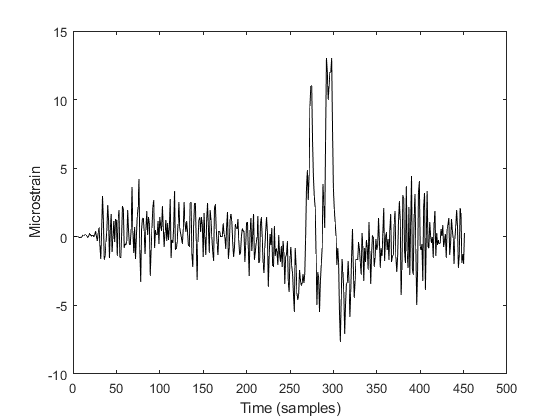


Data1 = textread('6035_Intact_Single3axle_TP1.txt');
plot(Data1,'k', 'Linewidth', 1)

xlabel('Time (samples)')
ylabel('Microstrain')


Test1_st40=Data1;

Test1_st40=Test1_st40';



Here I am isolating the peaks manually to later use only movemean function on other parts of response. The purpose is to keep the peaks as it is (since they are not usually noisy) and to only make other parts smooth. Another way is to use other denoising tecniques such as wavelet etc. 


T1=Test1_st40(1:271);
T2=Test1_st40(272:279);
T3=Test1_st40(280:286);
T4=Test1_st40(287:303);
T5=Test1_st40(304:end-33);


T1 = movmean(T1,[10 0]);
T3 = movmean(T3,[10 0]);
T5 = movmean(T5,[10 0]);


Test1_st40=[T1 T2 T3 T4 T5];

Test1_st40=Test1_st40';


Let's plot the denoised response

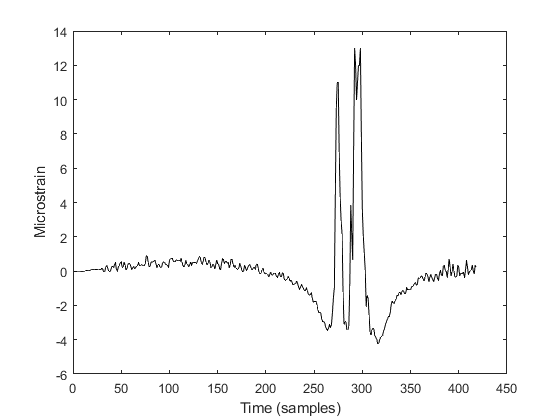


figure
plot(Test1_st40,'k', 'Linewidth', 1)

xlabel('Time (samples)')
ylabel('Microstrain')

So far, we removed the noise from damping ratio of zero directly caused in the CSI Bridge. Now, we add noise content and we denoise it again in a similar way.

Test1_st40=Test1_st40+0.4*randn(length(Test1_st40),1);


Let's plot the noisy response

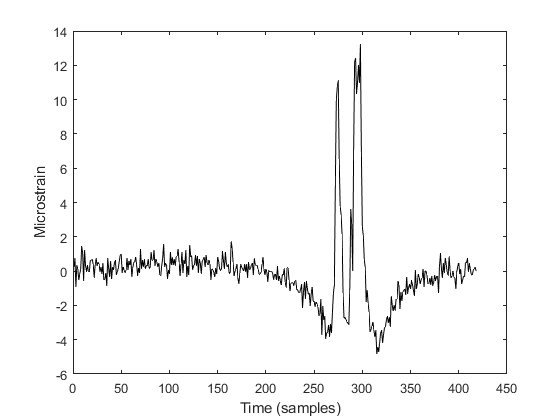


plot(Test1_st40,'k', 'Linewidth', 1)

xlabel('Time (samples)')
ylabel('Microstrain')

Test1_st40=Test1_st40';


Denoising the response

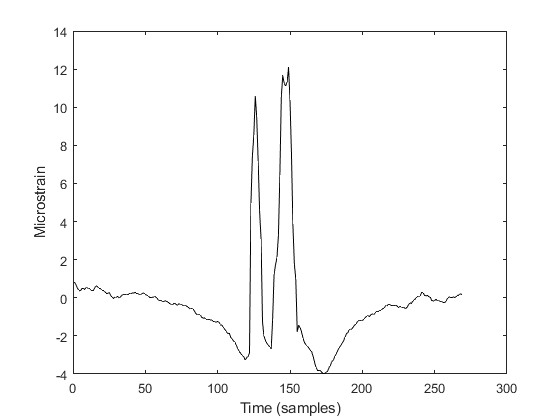


T1=Test1_st40(150:271);
T2=Test1_st40(272:279);
T3=Test1_st40(280:286);
T4=Test1_st40(287:303);
T5=Test1_st40(304:end);


T1 = movmean(T1,[10 0]);

T2=movmean(T2,[2 0]);

T3 = movmean(T3,[10 0]);

T4=movmean(T4,[2 0]);

T5 = movmean(T5,[10 0]);


Test1_st40=[T1 T2 T3 T4 T5];

Test1_st40=Test1_st40';

plot(Test1_st40,'k', 'Linewidth', 1)

xlabel('Time (samples)')
ylabel('Microstrain')

The envelope function is coded here to remove the global (non-localized) strain response. In this study, it was found that the ``Envelope'' function in MATLAB can successfully satisfy the requirements for global strain removal (explained in my dissertation) when a proper ``peak separation factor (n_p)'' is selected. The MATLAB code prepared for this study automatically checks different. $n_p$ values between 30-50 (found as the most effective range) and chooses the one that generates an envelope with smallest difference from P_1 (explained in my dissertation). To do this, a loop was programmed that changes the np value in each step and chooses the one with the lowest generated P_1 in the modified strain response (the non-localized response removed). 

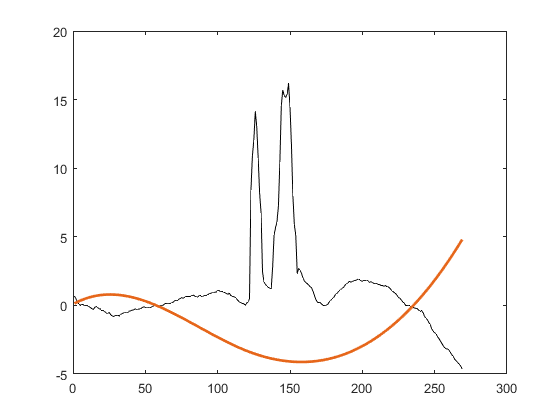


Cri_1=[];
AA=1;
XX=[30 35 40 45 50];
for BB=1:length(XX)
  [up1,low_test1] = envelope(Test1_st40,XX(BB),'peak');
  param_small = {'Color',[0.9 0.4 0.1],'Linewidth',2};
  
  Test1_st40_TRY=Test1_st40-low_test1;
  Cri_1(AA)=[abs(Test1_st40_TRY(131,1))];
  AA=AA+1;
end
Index = find(Cri_1==min(Cri_1));

if length(Index)>1
    Index=Index(1)
end


[up1,low_test1] = envelope(Test1_st40,XX(Index),'peak');
Test1_st40=Test1_st40-low_test1;
% min(Cri_1)


figure
plot(Test1_st40,'k', 'Linewidth', 1)
hold on
plot(low_test1,param_small{:});
hold off

The fitted curve sometimes may look a little weird but stil satisfy the requirements mentioned in chapter three of my dissertation and in that case will be fine. If does not satisfy the requirements properly (that most of the time does!) we should assign other XX values in the code above.

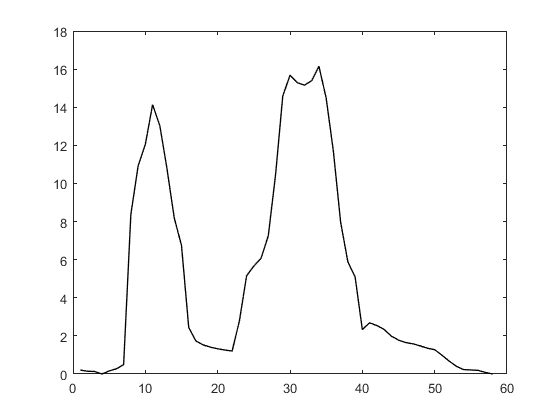

Test1_st40=Test1_st40(116:173);
figure
plot(Test1_st40,'k', 'Linewidth', 1)

## Inputs

Here we get the truck information. Please see the first paper (experimental case study) or my PhD dissertation (chapter 2) for details and to know what these parameters are. I have also commented them below for clarification


N_T1=3;          %% the number of axles
v1_T1=25;        %% speed m/s
f_T1=100;        %% sampling rate (Hz)
d1_T1=0;         %% the distance of the first axle from the first axle (m) --> This is always zero
d2_T1=4.5;       %% the distance of the second axle from the first axle (m) 
d3_T1=1.31;      %% the distance of the third axle from the first axle (m) 


% Axle weights

Weights_T1=[9.1 7.1 7.1];

% D vector using the d values already defined 

D1_vec_T1=[d1_T1 d1_T1+d2_T1 d1_T1+d2_T1+d3_T1];

% Calculating c values based on speed, sampling rate, and d values

c1_T1=D1_vec_T1(1)*f_T1/v1_T1;
c2_T1=D1_vec_T1(2)*f_T1/v1_T1;
c3_T1=D1_vec_T1(3)*f_T1/v1_T1;


C1_vec_T1=round([c1_T1 c2_T1 c3_T1]);

[row1_T1 col1_T1]=size(Test1_st40);
k1_T1=row1_T1;                      %% Total number of scans



This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), Weight vector (created from a truck axle weights which is considered for calibration), and dataaa (strain data) and returns the Matrix A. This matrix is later used for IL computation.


[A_mat_T1]=A_MATRIX(N_T1,k1_T1,C1_vec_T1,Weights_T1);

## Test 2 (3-axle_LANE2_TP2)

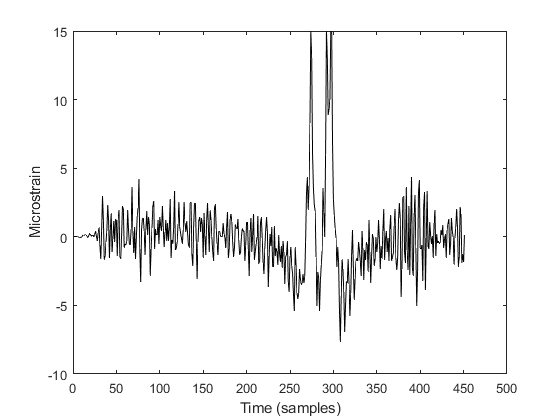

Data2 = textread('6035_Intact_Single3axle_TP2.txt');
plot(Data2,'k', 'Linewidth', 1)

xlabel('Time (samples)')
ylabel('Microstrain')

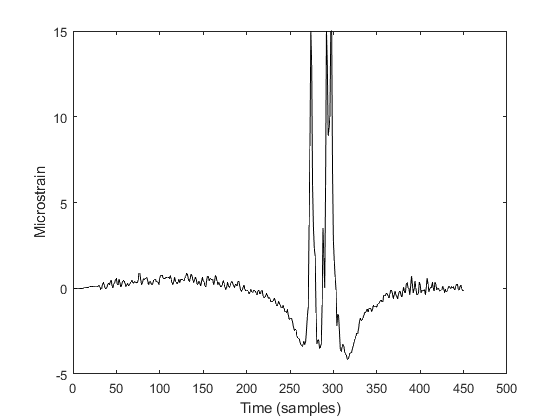

% 
Test2_st40=Data2;
Test2_st40=Test2_st40';

T1=Test2_st40(1:271);
T2=Test2_st40(272:279);
T3=Test2_st40(280:286);
T4=Test2_st40(287:303);
T5=Test2_st40(304:end);


T1 = movmean(T1,[10 0]);
T3 = movmean(T3,[10 0]);
T5 = movmean(T5,[10 0]);

Test2_st40=[T1 T2 T3 T4 T5];


Test2_st40=Test2_st40';


figure
plot(Test2_st40,'k', 'Linewidth', 1)

xlabel('Time (samples)')
ylabel('Microstrain')

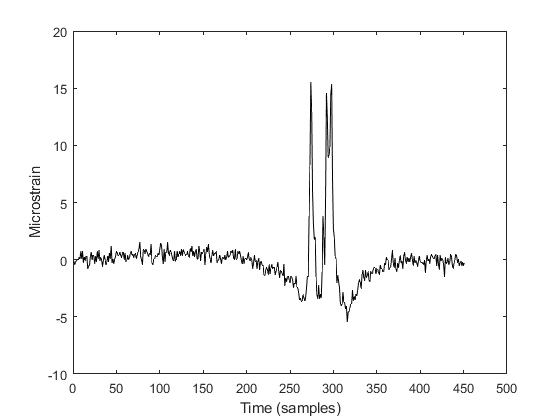


Test2_st40=Test2_st40+0.4*randn(length(Test2_st40),1);
plot(Test2_st40,'k', 'Linewidth', 1)

xlabel('Time (samples)')
ylabel('Microstrain')

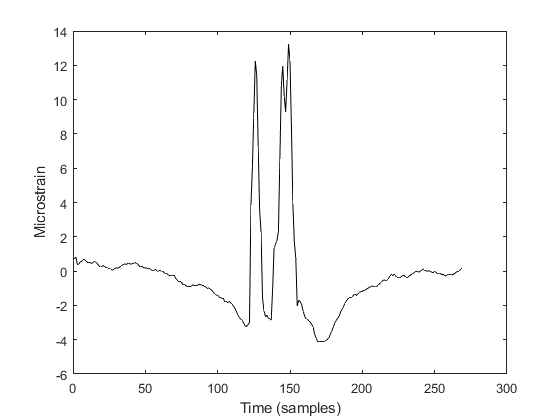

Test2_st40=Test2_st40';

T1=Test2_st40(150:271);
T2=Test2_st40(272:279);
T3=Test2_st40(280:286);
T4=Test2_st40(287:303);
T5=Test2_st40(304:end-33);

T1 = movmean(T1,[10 0]);

T2=movmean(T2,[2 0]);

T3 = movmean(T3,[10 0]);

T4=movmean(T4,[2 0]);

T5 = movmean(T5,[10 0]);


Test2_st40=[T1 T2 T3 T4 T5];

Test2_st40=Test2_st40';

plot(Test2_st40,'k', 'Linewidth', 1)

xlabel('Time (samples)')
ylabel('Microstrain')

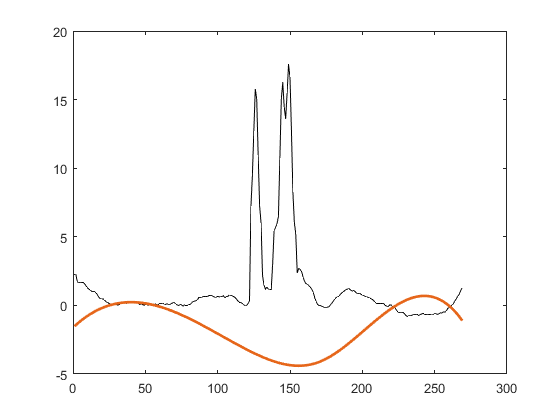

Cri_1=[];
AA=1;
XX=[25 30 35 40 45];
for BB=1:length(XX)
  [up2,low_test2] = envelope(Test2_st40,XX(BB),'peak');
  param_small = {'Color',[0.9 0.4 0.1],'Linewidth',2};
  
  Test2_st40_TRY=Test2_st40-low_test2;
  Cri_1(AA)=[abs(Test2_st40_TRY(131,1))];
  AA=AA+1;
end
Index = find(Cri_1==min(Cri_1));

if length(Index)>1
    Index=Index(1)
end


[up2,low_test2] = envelope(Test2_st40,XX(Index),'peak');
Test2_st40=Test2_st40-low_test2;
% min(Cri_1)


figure
plot(Test2_st40,'k', 'Linewidth', 1)
hold on
plot(low_test2,param_small{:});
hold off

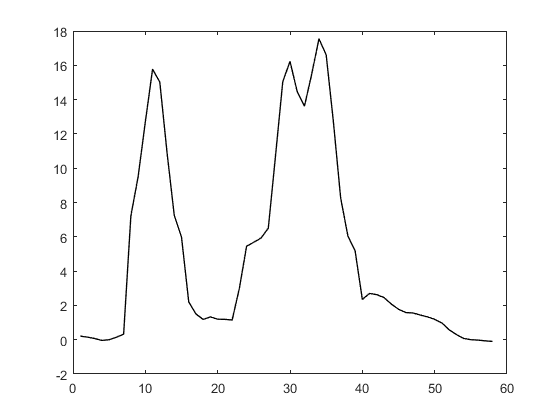

Test2_st40=Test2_st40(116:173);
figure
plot(Test2_st40,'k', 'Linewidth', 1)

## Inputs

N_T2=3;          %% the number of axles
v1_T2=25;     %% m/s
f_T2=100;        %% Hz
d1_T2=0;         %% m
d2_T2=4.5;      %% m
d3_T2=1.31;      %% m



Weights_T2=[9.1 7.1 7.1];

D1_vec_T2=[d1_T2 d1_T2+d2_T2 d1_T2+d2_T2+d3_T2];

c1_T2=D1_vec_T2(1)*f_T2/v1_T2;
c2_T2=D1_vec_T2(2)*f_T2/v1_T2;
c3_T2=D1_vec_T2(3)*f_T2/v1_T2;


C1_vec_T2=round([c1_T2 c2_T2 c3_T2]);

[row1_T2 col1_T2]=size(Test2_st40);
k1_T2=row1_T2;                      %% Total number of scans

%%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
%%% Weight vector (created from a truck axle weights which is considered for calibration), and dataaa (strain data)

[A_mat_T2]=A_MATRIX(N_T2,k1_T2,C1_vec_T2,Weights_T2);

## Test 3 (3-axle_LANE2_TP3)

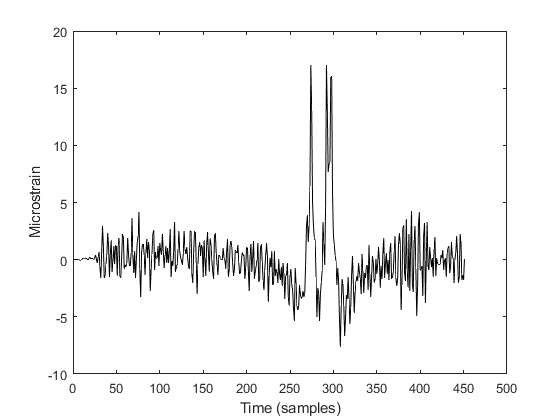

Data3 = textread('6035_Intact_Single3axle_TP3.txt');
plot(Data3,'k', 'Linewidth', 1)

xlabel('Time (samples)')
ylabel('Microstrain')

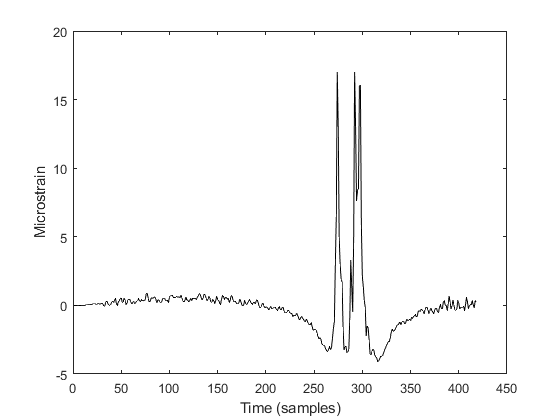

% 
Test3_st40=Data3;
Test3_st40=Test3_st40';

T1=Test3_st40(1:271);
T2=Test3_st40(272:279);
T3=Test3_st40(280:286);
T4=Test3_st40(287:303);
T5=Test3_st40(304:end-33);


T1 = movmean(T1,[10 0]);
T3 = movmean(T3,[10 0]);
T5 = movmean(T5,[10 0]);


Test3_st40=[T1 T2 T3 T4 T5];

Test3_st40=Test3_st40';

figure
plot(Test3_st40,'k', 'Linewidth', 1)

xlabel('Time (samples)')
ylabel('Microstrain')

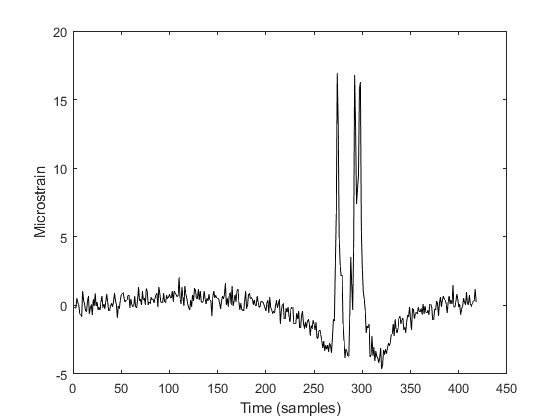

Test3_st40=Test3_st40+0.4*randn(length(Test3_st40),1);
plot(Test3_st40,'k', 'Linewidth', 1)

xlabel('Time (samples)')
ylabel('Microstrain')

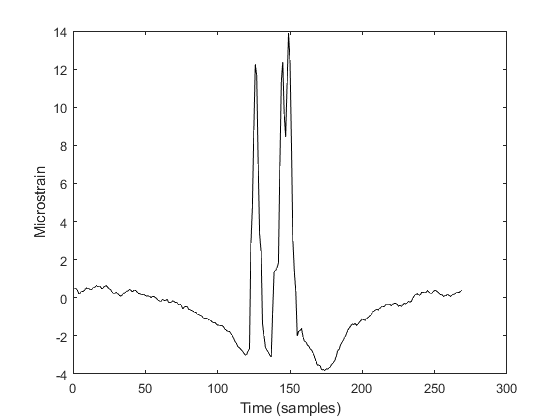



Test3_st40=Test3_st40';

T1=Test3_st40(150:271);
T2=Test3_st40(272:279);
T3=Test3_st40(280:286);
T4=Test3_st40(287:303);
T5=Test3_st40(304:end);

T1 = movmean(T1,[10 0]);

T2=movmean(T2,[2 0]);

T3 = movmean(T3,[10 0]);

T4=movmean(T4,[2 0]);

T5 = movmean(T5,[10 0]);


Test3_st40=[T1 T2 T3 T4 T5];

Test3_st40=Test3_st40';

plot(Test3_st40,'k', 'Linewidth', 1)

xlabel('Time (samples)')
ylabel('Microstrain')

Cri_1=[];
AA=1;
XX=[30 35 40 45 50];
for BB=1:length(XX)
  [up3,low_test3] = envelope(Test3_st40,XX(BB),'peak');
  param_small = {'Color',[0.9 0.4 0.1],'Linewidth',2};
  
  Test3_st40_TRY=Test3_st40-low_test3;
  Cri_1(AA)=[abs(Test3_st40_TRY(131,1))];
  AA=AA+1;
end
Index = find(Cri_1==min(Cri_1));

if length(Index)>1
    Index=Index(1)
end

Index = 1

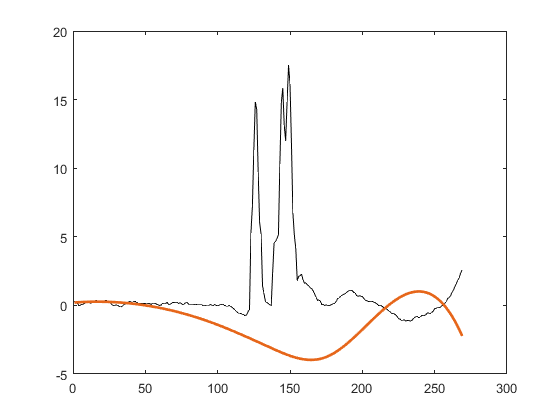



[up3,low_test3] = envelope(Test3_st40,XX(Index),'peak');
Test3_st40=Test3_st40-low_test3;
% min(Cri_1)


figure
plot(Test3_st40,'k', 'Linewidth', 1)
hold on
plot(low_test3,param_small{:});
hold off

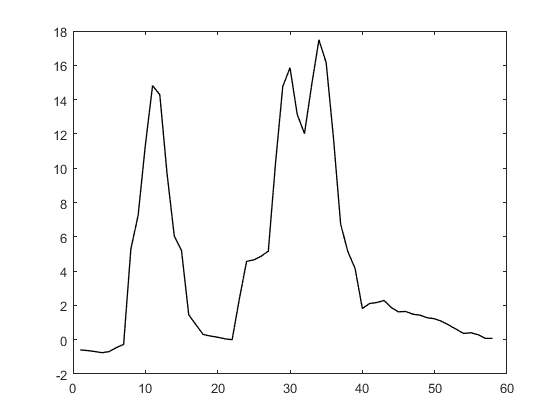

Test3_st40=Test3_st40(116:173);
figure
plot(Test3_st40,'k', 'Linewidth', 1)

## Inputs

N_T3=3;          %% the number of axles
v1_T3=25;     %% m/s
f_T3=100;        %% Hz
d1_T3=0;         %% m
d2_T3=4.5;      %% m
d3_T3=1.31;      %% m



Weights_T3=[9.1 7.1 7.1];

D1_vec_T3=[d1_T3 d1_T3+d2_T3 d1_T3+d2_T3+d3_T3];

c1_T3=D1_vec_T3(1)*f_T3/v1_T3;
c2_T3=D1_vec_T3(2)*f_T3/v1_T3;
c3_T3=D1_vec_T3(3)*f_T3/v1_T3;


C1_vec_T3=round([c1_T3 c2_T3 c3_T3]);

[row1_T3 col1_T3]=size(Test3_st40);
k1_T3=row1_T3;                      %% Total number of scans

%%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
%%% Weight vector (created from a truck axle weights which is considered for calibration), and dataaa (strain data)

[A_mat_T3]=A_MATRIX(N_T3,k1_T3,C1_vec_T3,Weights_T3);

## Test 4 (4-axle_LANE2_TP1)

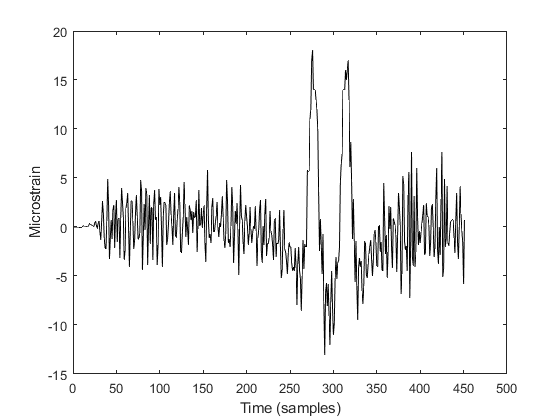

Data4 = textread('6035_Intact_Single4axle_TP1.txt');
plot(Data4,'k', 'Linewidth', 1)

xlabel('Time (samples)')
ylabel('Microstrain')

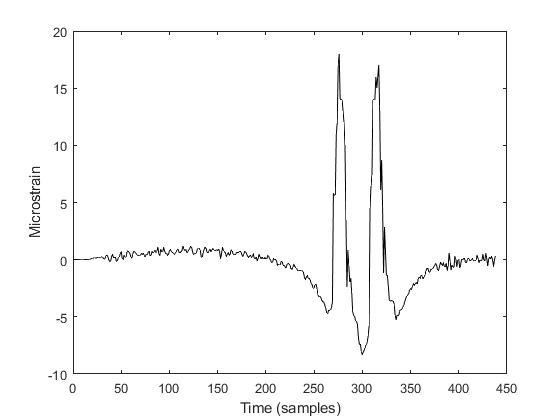

% 
Test4_st40=Data4;
Test4_st40=Test4_st40';

T1=Test4_st40(1:269);
T2=Test4_st40(270:284);
T3=Test4_st40(285:307);
T4=Test4_st40(308:322);
T5=Test4_st40(323:end-13);


T1 = movmean(T1,[10 0]);
T3 = movmean(T3,[10 0]);
T5 = movmean(T5,[10 0]);

Test4_st40=[T1 T2 T3 T4 T5];
Test4_st40=Test4_st40';

figure
plot(Test4_st40,'k', 'Linewidth', 1)

xlabel('Time (samples)')
ylabel('Microstrain')

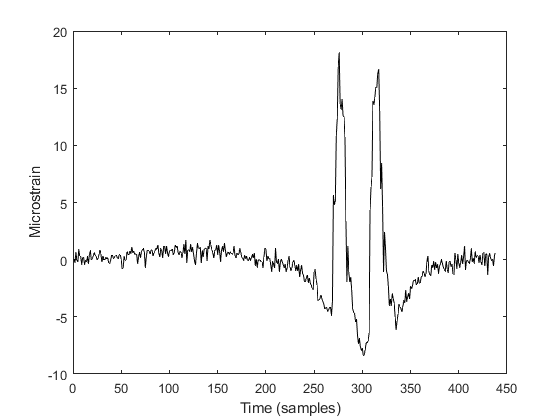

Test4_st40=Test4_st40+0.4*randn(length(Test4_st40),1);
plot(Test4_st40,'k', 'Linewidth', 1)

xlabel('Time (samples)')
ylabel('Microstrain')

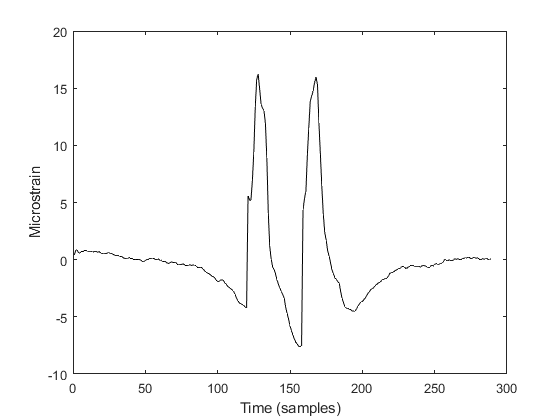



Test4_st40=Test4_st40';

T1=Test4_st40(150:269);
T2=Test4_st40(270:284);
T3=Test4_st40(285:307);
T4=Test4_st40(308:322);
T5=Test4_st40(323:end);


T1 = movmean(T1,[10 0]);

T2=movmean(T2,[2 0]);

T3 = movmean(T3,[10 0]);

T4=movmean(T4,[2 0]);

T5 = movmean(T5,[10 0]);


Test4_st40=[T1 T2 T3 T4 T5];

Test4_st40=Test4_st40';

plot(Test4_st40,'k', 'Linewidth', 1)

xlabel('Time (samples)')
ylabel('Microstrain')

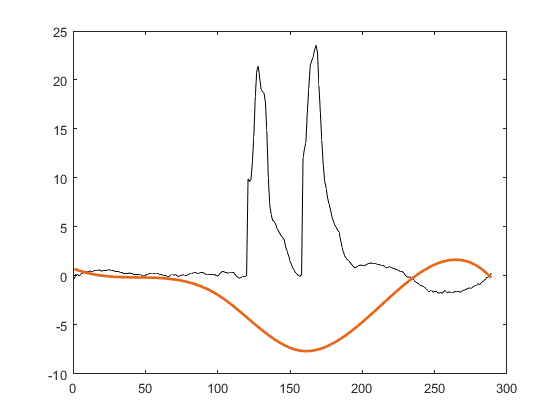

Cri_1=[];
AA=1;
XX=[30 35 40 45 50];
for BB=1:length(XX)
  [up4,low_test4] = envelope(Test4_st40,XX(BB),'peak');
  param_small = {'Color',[0.9 0.4 0.1],'Linewidth',2};
  
  Test4_st40_TRY=Test4_st40-low_test4;
  Cri_1(AA)=[abs(Test4_st40_TRY(131,1))];
  AA=AA+1;
end
Index = find(Cri_1==min(Cri_1));

if length(Index)>1
    Index=Index(1)
end


[up4,low_test4] = envelope(Test4_st40,XX(Index),'peak');
Test4_st40=Test4_st40-low_test4;
% min(Cri_1)


figure
plot(Test4_st40,'k', 'Linewidth', 1)
hold on
plot(low_test4,param_small{:});
hold off

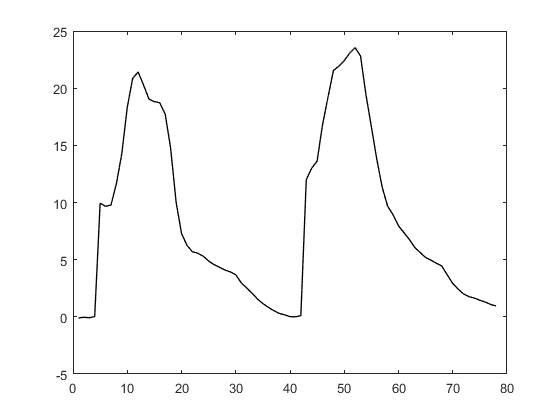

Test4_st40=Test4_st40(117:194);
figure
plot(Test4_st40,'k', 'Linewidth', 1)

## Inputs

N_T4=4;          %% the number of axles
v1_T4=25;     %% m/s
f_T4=100;        %% Hz
d1_T4=0;         %% m
d2_T4=1.4;      %% m
d3_T4=8;      %% m
d4_T4=1.4;     %% m



Weights_T4=[9 9 9 9];

D1_vec_T4=[d1_T4 d1_T4+d2_T4 d1_T4+d2_T4+d3_T4 d1_T4+d2_T4+d3_T4+d4_T4];

c1_T4=D1_vec_T4(1)*f_T4/v1_T4;
c2_T4=D1_vec_T4(2)*f_T4/v1_T4;
c3_T4=D1_vec_T4(3)*f_T4/v1_T4;
c4_T4=D1_vec_T4(4)*f_T4/v1_T4;


C1_vec_T4=round([c1_T4 c2_T4 c3_T4 c4_T4]);

[row1_T4 col1_T4]=size(Test4_st40);
k1_T4=row1_T4;                      %% Total number of scans

%%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
%%% Weight vector (created from a truck axle weights which is considered for calibration), and dataaa (strain data)

[A_mat_T4]=A_MATRIX(N_T4,k1_T4,C1_vec_T4,Weights_T4);


## Test 5 (4-axle_LANE2_TP2)

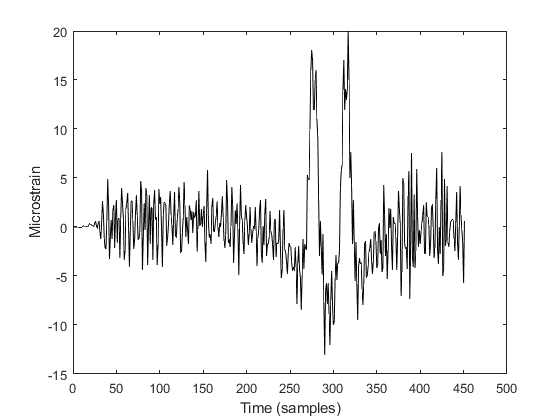

Data5 = textread('6035_Intact_Single4axle_TP2.txt');
plot(Data5,'k', 'Linewidth', 1)

xlabel('Time (samples)')
ylabel('Microstrain')

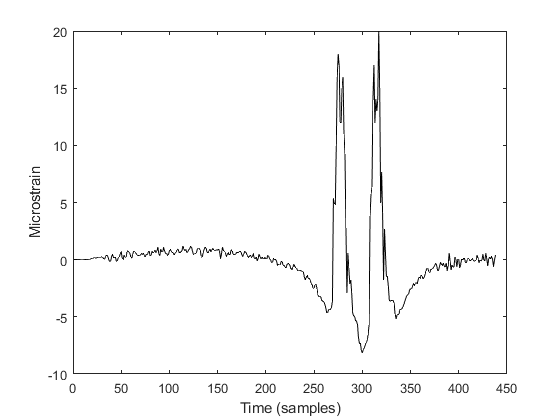

% 
Test5_st40=Data5;
Test5_st40=Test5_st40';

T1=Test5_st40(1:269);
T2=Test5_st40(270:284);
T3=Test5_st40(285:307);
T4=Test5_st40(308:322);
T5=Test5_st40(323:end-13);


T1 = movmean(T1,[10 0]);
T3 = movmean(T3,[10 0]);
T5 = movmean(T5,[10 0]);

Test5_st40=[T1 T2 T3 T4 T5];
Test5_st40=Test5_st40';

figure
plot(Test5_st40,'k', 'Linewidth', 1)

xlabel('Time (samples)')
ylabel('Microstrain')

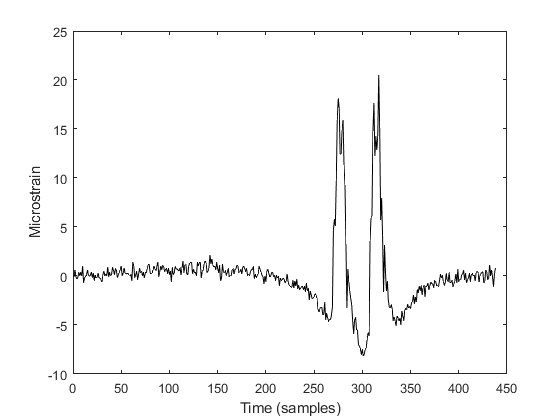

Test5_st40=Test5_st40+0.4*randn(length(Test5_st40),1);
plot(Test5_st40,'k', 'Linewidth', 1)

xlabel('Time (samples)')
ylabel('Microstrain')

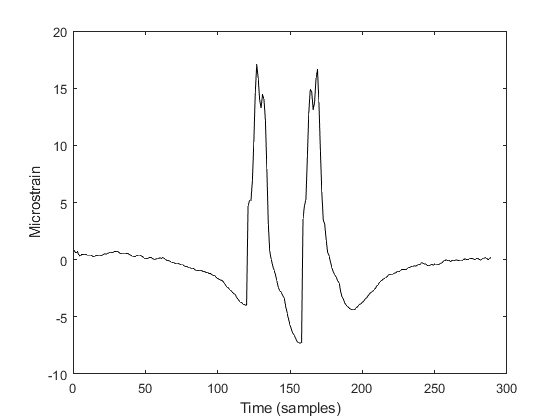


Test5_st40=Test5_st40';

T1=Test5_st40(150:269);
T2=Test5_st40(270:284);
T3=Test5_st40(285:307);
T4=Test5_st40(308:322);
T5=Test5_st40(323:end);


T1 = movmean(T1,[10 0]);

T2=movmean(T2,[2 0]);

T3 = movmean(T3,[10 0]);

T4=movmean(T4,[2 0]);

T5 = movmean(T5,[10 0]);


Test5_st40=[T1 T2 T3 T4 T5];

Test5_st40=Test5_st40';

plot(Test5_st40,'k', 'Linewidth', 1)

xlabel('Time (samples)')
ylabel('Microstrain')

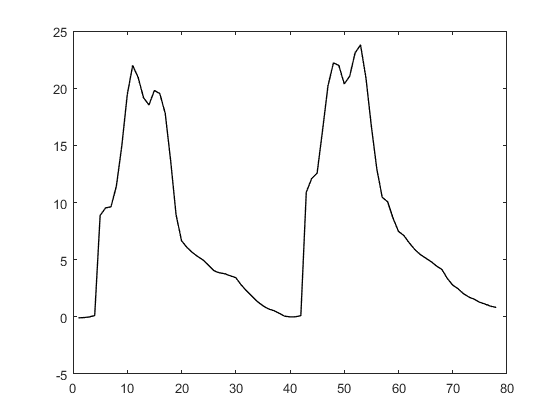

Cri_1=[];
AA=1;
XX=[30 35 40 45 50];
for BB=1:length(XX)
  [up5,low_test5] = envelope(Test5_st40,XX(BB),'peak');
  param_small = {'Color',[0.9 0.4 0.1],'Linewidth',2};
  
  Test5_st40_TRY=Test5_st40-low_test5;
  Cri_1(AA)=[abs(Test5_st40_TRY(131,1))];
  AA=AA+1;
end
Index = find(Cri_1==min(Cri_1));

if length(Index)>1
    Index=Index(1)
end


[up5,low_test5] = envelope(Test5_st40,XX(Index),'peak');
Test5_st40=Test5_st40-low_test5;
% min(Cri_1)


% figure
% plot(Test5_st40,'k', 'Linewidth', 1)
% hold on
% plot(low_test5,param_small{:});
% hold off
Test5_st40=Test5_st40(117:194);
figure
plot(Test5_st40,'k', 'Linewidth', 1)

## Inputs

N_T5=4;          %% the number of axles
v1_T5=25;     %% m/s
f_T5=100;        %% Hz
d1_T5=0;         %% m
d2_T5=1.4;      %% m
d3_T5=8;      %% m
d4_T5=1.4;     %% m



Weights_T5=[9 9 9 9];

D1_vec_T5=[d1_T5 d1_T5+d2_T5 d1_T5+d2_T5+d3_T5 d1_T5+d2_T5+d3_T5+d4_T5];

c1_T5=D1_vec_T5(1)*f_T5/v1_T5;
c2_T5=D1_vec_T5(2)*f_T5/v1_T5;
c3_T5=D1_vec_T5(3)*f_T5/v1_T5;
c4_T5=D1_vec_T5(4)*f_T5/v1_T5;


C1_vec_T5=round([c1_T5 c2_T5 c3_T5 c4_T5]);

[row1_T5 col1_T5]=size(Test5_st40);
k1_T5=row1_T5;                      %% Total number of scans

%%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
%%% Weight vector (created from a truck axle weights which is considered for calibration), and dataaa (strain data)

[A_mat_T5]=A_MATRIX(N_T5,k1_T5,C1_vec_T5,Weights_T5);



## Test 6 (4-axle_LANE2_TP3)

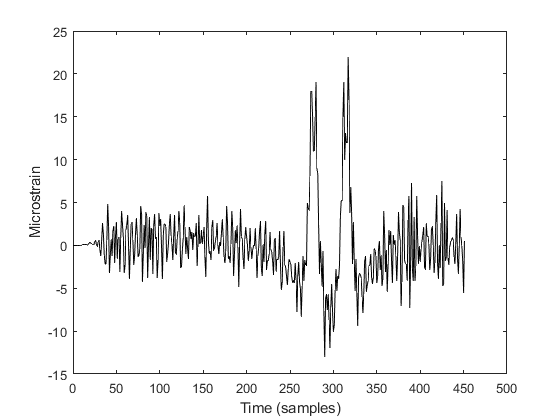

Data6 = textread('6035_Intact_Single4axle_TP3.txt');
plot(Data6,'k', 'Linewidth', 1)

xlabel('Time (samples)')
ylabel('Microstrain')

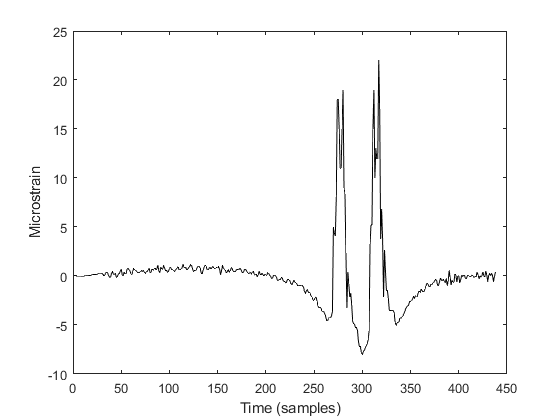

% 
Test6_st40=Data6;
Test6_st40=Test6_st40';

T1=Test6_st40(1:269);
T2=Test6_st40(270:284);
T3=Test6_st40(285:307);
T4=Test6_st40(308:322);
T5=Test6_st40(323:end-13);


T1 = movmean(T1,[10 0]);
T3 = movmean(T3,[10 0]);
T5 = movmean(T5,[10 0]);

Test6_st40=[T1 T2 T3 T4 T5];

Test6_st40=Test6_st40';

figure
plot(Test6_st40,'k', 'Linewidth', 1)

xlabel('Time (samples)')
ylabel('Microstrain')

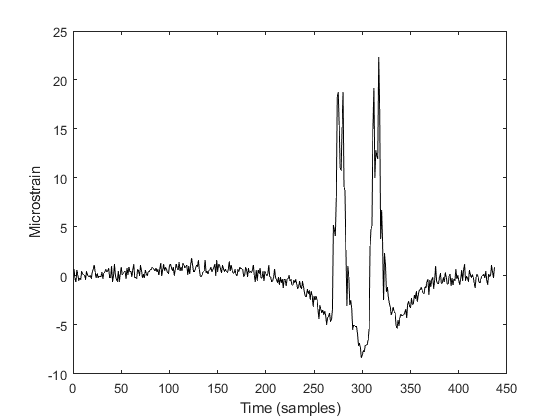

Test6_st40=Test6_st40+0.4*randn(length(Test6_st40),1);
plot(Test6_st40,'k', 'Linewidth', 1)

xlabel('Time (samples)')
ylabel('Microstrain')

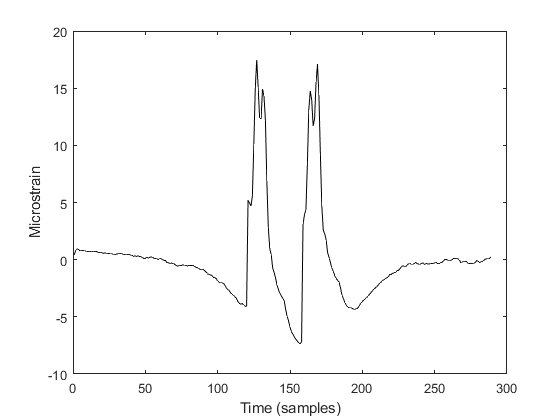



Test6_st40=Test6_st40';

T1=Test6_st40(150:269);
T2=Test6_st40(270:284);
T3=Test6_st40(285:307);
T4=Test6_st40(308:322);
T5=Test6_st40(323:end);

T1 = movmean(T1,[10 0]);

T2=movmean(T2,[2 0]);

T3 = movmean(T3,[10 0]);

T4=movmean(T4,[2 0]);

T5 = movmean(T5,[10 0]);


Test6_st40=[T1 T2 T3 T4 T5];

Test6_st40=Test6_st40';

plot(Test6_st40,'k', 'Linewidth', 1)

xlabel('Time (samples)')
ylabel('Microstrain')

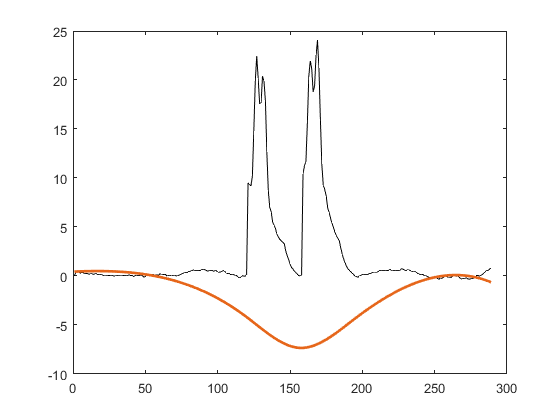

Cri_1=[];
AA=1;
XX=[30 35 40 45 50];
for BB=1:length(XX)
  [up6,low_test6] = envelope(Test6_st40,XX(BB),'peak');
  param_small = {'Color',[0.9 0.4 0.1],'Linewidth',2};
  
  Test6_st40_TRY=Test6_st40-low_test6;
  Cri_1(AA)=[abs(Test6_st40_TRY(131,1))];
  AA=AA+1;
end
Index = find(Cri_1==min(Cri_1));

if length(Index)>1
    Index=Index(1)
end


[up6,low_test6] = envelope(Test6_st40,XX(Index),'peak');
Test6_st40=Test6_st40-low_test6;
% min(Cri_1)


figure
plot(Test6_st40,'k', 'Linewidth', 1)
hold on
plot(low_test6,param_small{:});
hold off

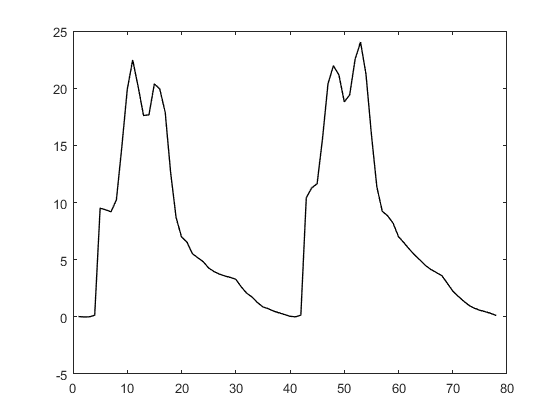

Test6_st40=Test6_st40(117:194);
figure
plot(Test6_st40,'k', 'Linewidth', 1)

## Inputs

N_T6=4;          %% the number of axles
v1_T6=25;     %% m/s
f_T6=100;        %% Hz
d1_T6=0;         %% m
d2_T6=1.4;      %% m
d3_T6=8;      %% m
d4_T6=1.4;     %% m



Weights_T6=[9 9 9 9];

D1_vec_T6=[d1_T6 d1_T6+d2_T6 d1_T6+d2_T6+d3_T6 d1_T6+d2_T6+d3_T6+d4_T6];

c1_T6=D1_vec_T6(1)*f_T6/v1_T6;
c2_T6=D1_vec_T6(2)*f_T6/v1_T6;
c3_T6=D1_vec_T6(3)*f_T6/v1_T6;
c4_T6=D1_vec_T6(4)*f_T6/v1_T6;


C1_vec_T6=round([c1_T6 c2_T6 c3_T6 c4_T6]);

[row1_T6 col1_T6]=size(Test6_st40);
k1_T6=row1_T6;                      %% Total number of scans

%%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
%%% Weight vector (created from a truck axle weights which is considered for calibration), and dataaa (strain data)

[A_mat_T6]=A_MATRIX(N_T6,k1_T6,C1_vec_T6,Weights_T6);


## Test 7 (5-axle_LANE2_TP1)

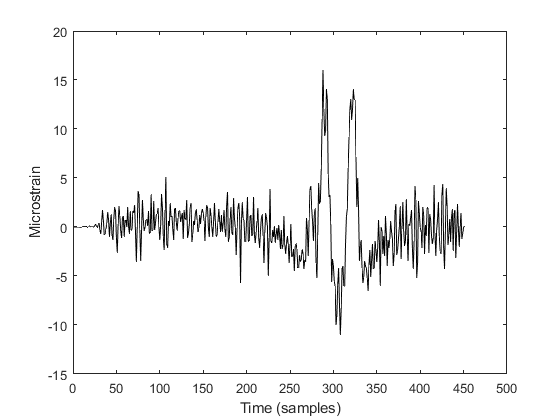

Data7 = textread('6035_Intact_Single5axle_TP1.txt');
plot(Data7,'k', 'Linewidth', 1)

xlabel('Time (samples)')
ylabel('Microstrain')

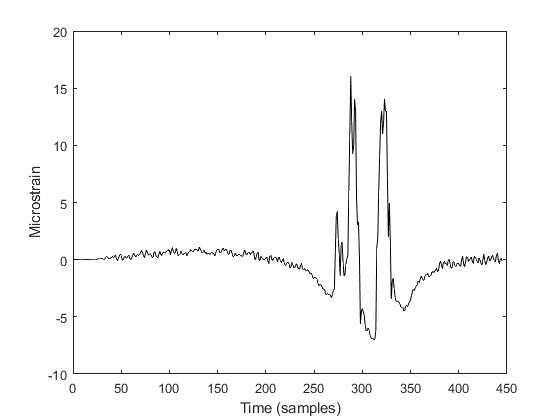

% 
Test7_st40=Data7;
Test7_st40=Test7_st40';

T1=Test7_st40(1:271);
T2=Test7_st40(272:277);
T3=Test7_st40(278:285);
T4=Test7_st40(286:297);
T5=Test7_st40(298:314);
T6=Test7_st40(315:330);
T7=Test7_st40(331:end-6);


T1 = movmean(T1,[10 0]);
T3 = movmean(T3,[10 0]);
T5 = movmean(T5,[10 0]);
T7 = movmean(T7,[10 0]);

Test7_st40=[T1 T2 T3 T4 T5 T6 T7];
Test7_st40=Test7_st40';

figure
plot(Test7_st40,'k', 'Linewidth', 1)

xlabel('Time (samples)')
ylabel('Microstrain')

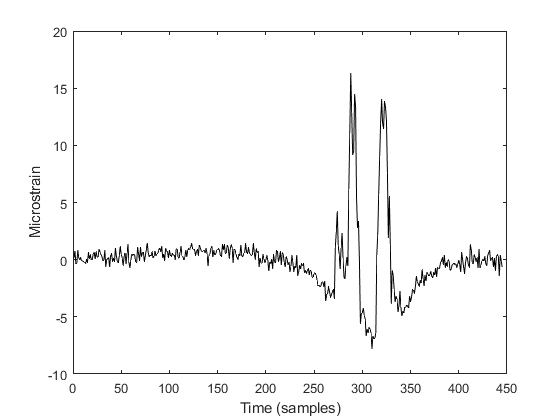

Test7_st40=Test7_st40+0.4*randn(length(Test7_st40),1);
plot(Test7_st40,'k', 'Linewidth', 1)

xlabel('Time (samples)')
ylabel('Microstrain')

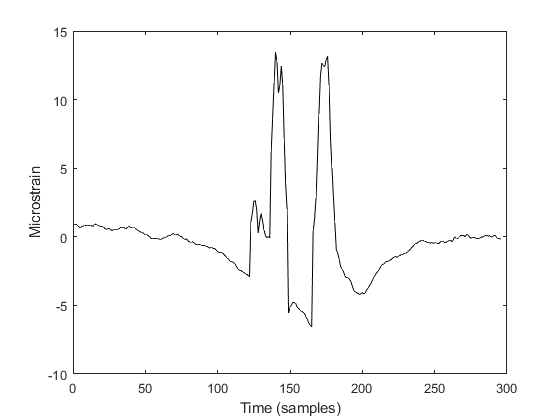



Test7_st40=Test7_st40';

T1=Test7_st40(150:271);
T2=Test7_st40(272:277);
T3=Test7_st40(278:285);
T4=Test7_st40(286:297);
T5=Test7_st40(298:314);
T6=Test7_st40(315:330);
T7=Test7_st40(331:end);

T1 = movmean(T1,[10 0]);

T2=movmean(T2,[2 0]);

T3 = movmean(T3,[10 0]);

T4=movmean(T4,[2 0]);

T5 = movmean(T5,[10 0]);

T6 = movmean(T6,[2 0]);
T7 = movmean(T7,[10 0]);

Test7_st40=[T1 T2 T3 T4 T5 T6 T7];

Test7_st40=Test7_st40';

plot(Test7_st40,'k', 'Linewidth', 1)

xlabel('Time (samples)')
ylabel('Microstrain')

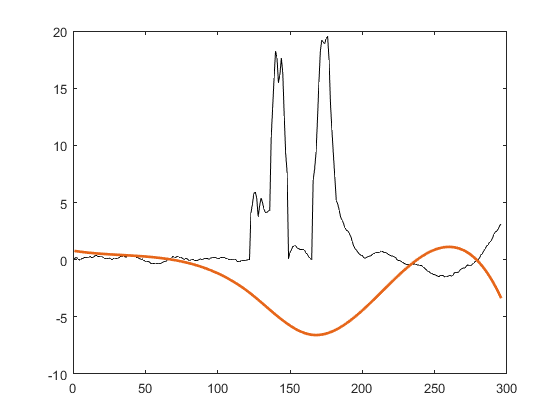

Cri_1=[];
AA=1;
XX=[30 35 40 45 50];
for BB=1:length(XX)
  [up7,low_test7] = envelope(Test7_st40,XX(BB),'peak');
  param_small = {'Color',[0.9 0.4 0.1],'Linewidth',2};
  
  Test7_st40_TRY=Test7_st40-low_test7;
  Cri_1(AA)=[abs(Test7_st40_TRY(131,1))];
  AA=AA+1;
end
Index = find(Cri_1==min(Cri_1));

if length(Index)>1
    Index=Index(1)
end


[up7,low_test7] = envelope(Test7_st40,XX(Index),'peak');
Test7_st40=Test7_st40-low_test7;
% min(Cri_1)


figure
plot(Test7_st40,'k', 'Linewidth', 1)
hold on
plot(low_test7,param_small{:});
hold off

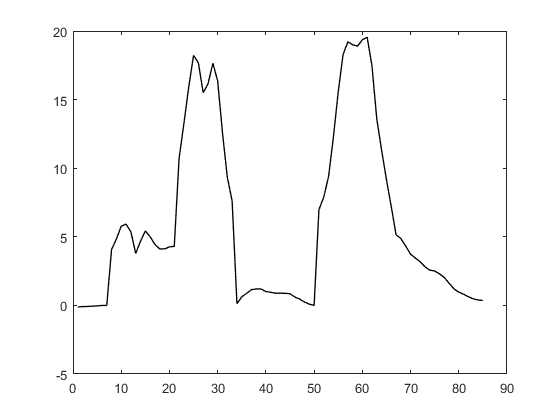

Test7_st40=Test7_st40(116:200);
figure
plot(Test7_st40,'k', 'Linewidth', 1)

## Inputs

N_T7=5;          %% the number of axles
v1_T7=25;     %% m/s
f_T7=100;        %% Hz
d1_T7=0;         %% m
d2_T7=3.3528;      %% m
d3_T7=1.2192;      %% m
d4_T7=6.7056;     %% m
d5_T7=1.2192;      %% m


Weights_T7=[4.54 7.03 7.03 7.03 7.03];

D1_vec_T7=[d1_T7 d1_T7+d2_T7 d1_T7+d2_T7+d3_T7 d1_T7+d2_T7+d3_T7+d4_T7 d1_T7+d2_T7+d3_T7+d4_T7+d5_T7];

c1_T7=D1_vec_T7(1)*f_T7/v1_T7;
c2_T7=D1_vec_T7(2)*f_T7/v1_T7;
c3_T7=D1_vec_T7(3)*f_T7/v1_T7;
c4_T7=D1_vec_T7(4)*f_T7/v1_T7;
c5_T7=D1_vec_T7(5)*f_T7/v1_T7;

C1_vec_T7=round([c1_T7 c2_T7 c3_T7 c4_T7 c5_T7]);

[row1_T7 col1_T7]=size(Test7_st40);
k1_T7=row1_T7;                      %% Total number of scans

%%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
%%% Weight vector (created from a truck axle weights which is considered for calibration), and dataaa (strain data)

[A_mat_T7]=A_MATRIX(N_T7,k1_T7,C1_vec_T7,Weights_T7);

## Test 8 (5-axle_LANE2_TP2)

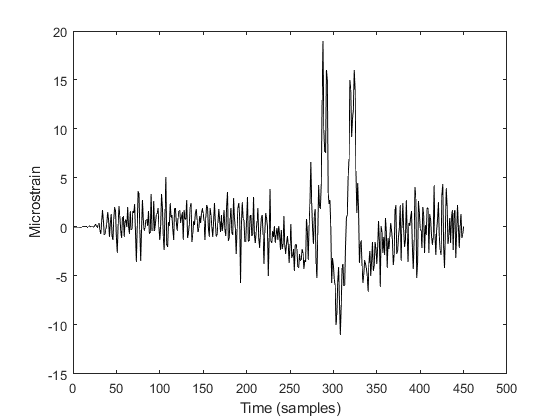

Data8 = textread('6035_Intact_Single5axle_TP2.txt');
plot(Data8,'k', 'Linewidth', 1)

xlabel('Time (samples)')
ylabel('Microstrain')

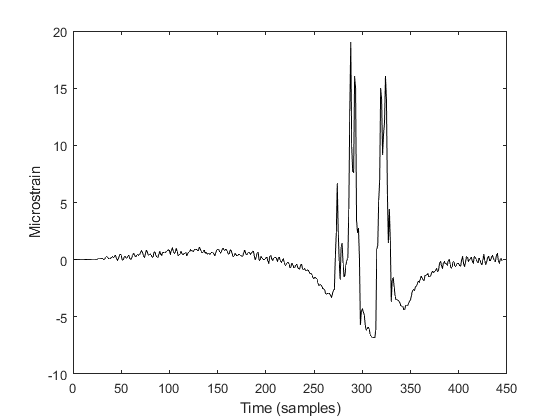

% 
Test8_st40=Data8;
Test8_st40=Test8_st40';

T1=Test8_st40(1:271);
T2=Test8_st40(272:277);
T3=Test8_st40(278:285);
T4=Test8_st40(286:297);
T5=Test8_st40(298:314);
T6=Test8_st40(315:330);
T7=Test8_st40(331:end-6);


T1 = movmean(T1,[10 0]);
T3 = movmean(T3,[10 0]);
T5 = movmean(T5,[10 0]);
T7 = movmean(T7,[10 0]);

Test8_st40=[T1 T2 T3 T4 T5 T6 T7];
Test8_st40=Test8_st40';

figure
plot(Test8_st40,'k', 'Linewidth', 1)

xlabel('Time (samples)')
ylabel('Microstrain')

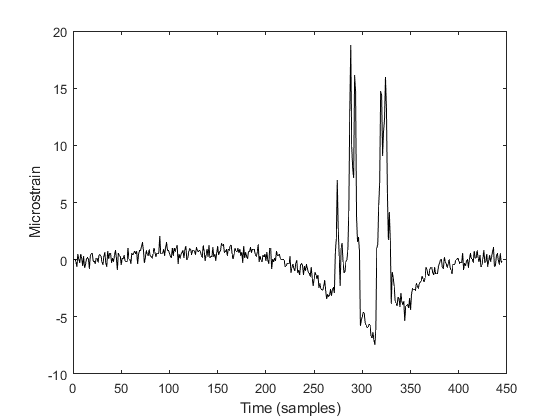

Test8_st40=Test8_st40+0.4*randn(length(Test8_st40),1);
plot(Test8_st40,'k', 'Linewidth', 1)

xlabel('Time (samples)')
ylabel('Microstrain')

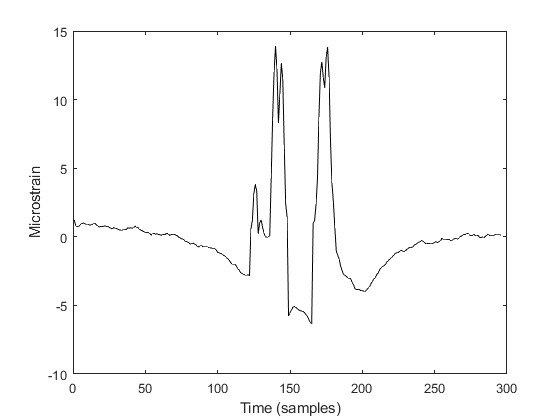



Test8_st40=Test8_st40';

T1=Test8_st40(150:271);
T2=Test8_st40(272:277);
T3=Test8_st40(278:285);
T4=Test8_st40(286:297);
T5=Test8_st40(298:314);
T6=Test8_st40(315:330);
T7=Test8_st40(331:end);


T1 = movmean(T1,[10 0]);

T2=movmean(T2,[2 0]);

T3 = movmean(T3,[10 0]);

T4=movmean(T4,[2 0]);

T5 = movmean(T5,[10 0]);

T6 = movmean(T6,[2 0]);

T7 = movmean(T7,[10 0]);


Test8_st40=[T1 T2 T3 T4 T5 T6 T7];

Test8_st40=Test8_st40';

plot(Test8_st40,'k', 'Linewidth', 1)

xlabel('Time (samples)')
ylabel('Microstrain')

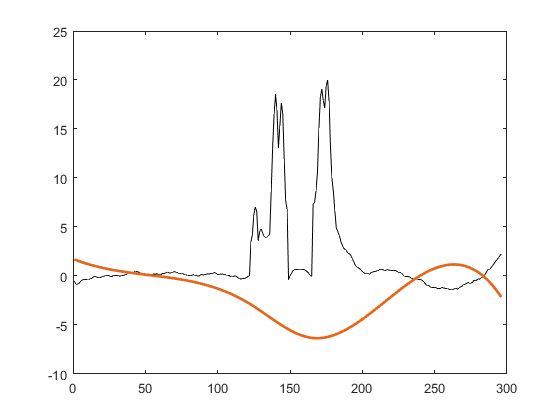

Cri_1=[];
AA=1;
XX=[30 35 40 45 50];
for BB=1:length(XX)
  [up8,low_test8] = envelope(Test8_st40,XX(BB),'peak');
  param_small = {'Color',[0.9 0.4 0.1],'Linewidth',2};
  
  Test8_st40_TRY=Test8_st40-low_test8;
  Cri_1(AA)=[abs(Test8_st40_TRY(131,1))];
  AA=AA+1;
end
Index = find(Cri_1==min(Cri_1));

if length(Index)>1
    Index=Index(1)
end


[up8,low_test8] = envelope(Test8_st40,XX(Index),'peak');
Test8_st40=Test8_st40-low_test8;
% min(Cri_1)


figure
plot(Test8_st40,'k', 'Linewidth', 1)
hold on
plot(low_test8,param_small{:});
hold off

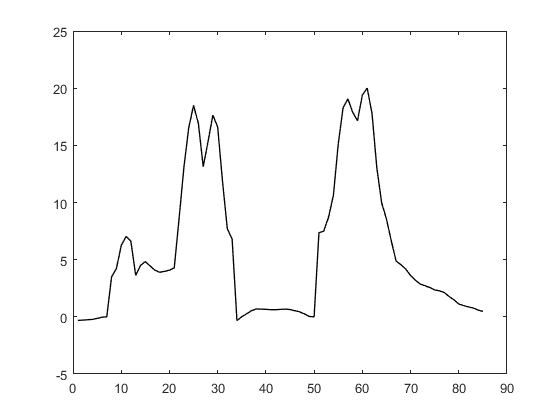

Test8_st40=Test8_st40(116:200);
figure
plot(Test8_st40,'k', 'Linewidth', 1)

## Inputs

N_T8=5;          %% the number of axles
v1_T8=25;     %% m/s
f_T8=100;        %% Hz
d1_T8=0;         %% m
d2_T8=3.3528;      %% m
d3_T8=1.2192;      %% m
d4_T8=6.7056;     %% m
d5_T8=1.2192;      %% m


Weights_T8=[4.54 7.03 7.03 7.03 7.03];

D1_vec_T8=[d1_T8 d1_T8+d2_T8 d1_T8+d2_T8+d3_T8 d1_T8+d2_T8+d3_T8+d4_T8 d1_T8+d2_T8+d3_T8+d4_T8+d5_T8];

c1_T8=D1_vec_T8(1)*f_T8/v1_T8;
c2_T8=D1_vec_T8(2)*f_T8/v1_T8;
c3_T8=D1_vec_T8(3)*f_T8/v1_T8;
c4_T8=D1_vec_T8(4)*f_T8/v1_T8;
c5_T8=D1_vec_T8(5)*f_T8/v1_T8;

C1_vec_T8=round([c1_T8 c2_T8 c3_T8 c4_T8 c5_T8]);

[row1_T8 col1_T8]=size(Test8_st40);
k1_T8=row1_T8;                      %% Total number of scans

%%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
%%% Weight vector (created from a truck axle weights which is considered for calibration), and dataaa (strain data)

[A_mat_T8]=A_MATRIX(N_T8,k1_T8,C1_vec_T8,Weights_T8);


## Test 9 (5-axle_LANE2_TP3)

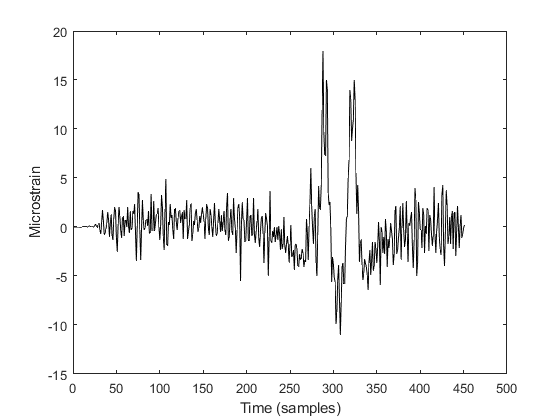

Data9 = textread('6035_Intact_Single5axle_TP3.txt');
plot(Data9,'k', 'Linewidth', 1)

xlabel('Time (samples)')
ylabel('Microstrain')

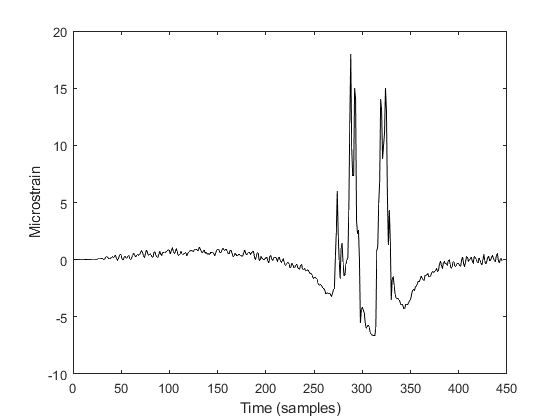

% 
Test9_st40=Data9;
Test9_st40=Test9_st40';

T1=Test9_st40(1:271);
T2=Test9_st40(272:277);
T3=Test9_st40(278:285);
T4=Test9_st40(286:297);
T5=Test9_st40(298:314);
T6=Test9_st40(315:330);
T7=Test9_st40(331:end-6);


T1 = movmean(T1,[10 0]);
T3 = movmean(T3,[10 0]);
T5 = movmean(T5,[10 0]);
T7 = movmean(T7,[10 0]);

Test9_st40=[T1 T2 T3 T4 T5 T6 T7];
Test9_st40=Test9_st40';

figure
plot(Test9_st40,'k', 'Linewidth', 1)

xlabel('Time (samples)')
ylabel('Microstrain')

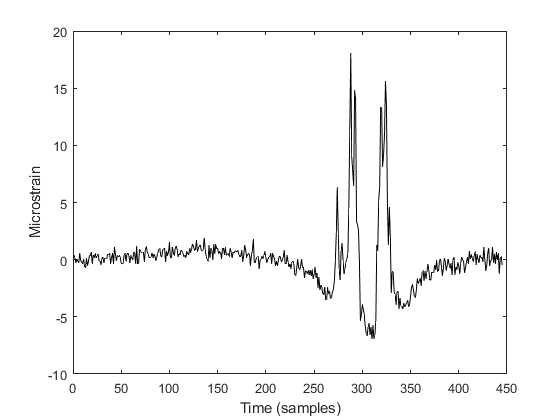

Test9_st40=Test9_st40+0.4*randn(length(Test9_st40),1);
plot(Test9_st40,'k', 'Linewidth', 1)

xlabel('Time (samples)')
ylabel('Microstrain')

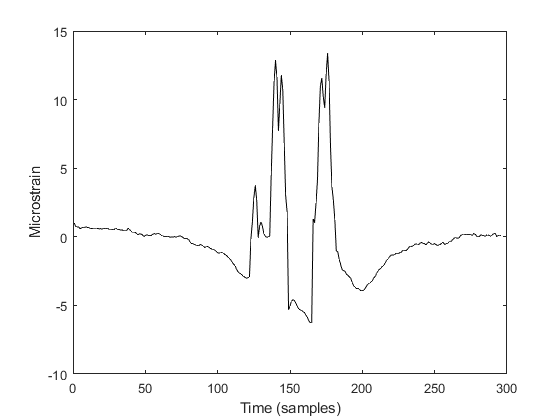



Test9_st40=Test9_st40';

T1=Test9_st40(150:271);
T2=Test9_st40(272:277);
T3=Test9_st40(278:285);
T4=Test9_st40(286:297);
T5=Test9_st40(298:314);
T6=Test9_st40(315:330);
T7=Test9_st40(331:end);



T1 = movmean(T1,[10 0]);

T2=movmean(T2,[2 0]);

T3 = movmean(T3,[10 0]);

T4=movmean(T4,[2 0]);

T5 = movmean(T5,[10 0]);

T6=movmean(T6,[2 0]);

T7 = movmean(T7,[10 0]);


Test9_st40=[T1 T2 T3 T4 T5 T6 T7];

Test9_st40=Test9_st40';

plot(Test9_st40,'k', 'Linewidth', 1)

xlabel('Time (samples)')
ylabel('Microstrain')

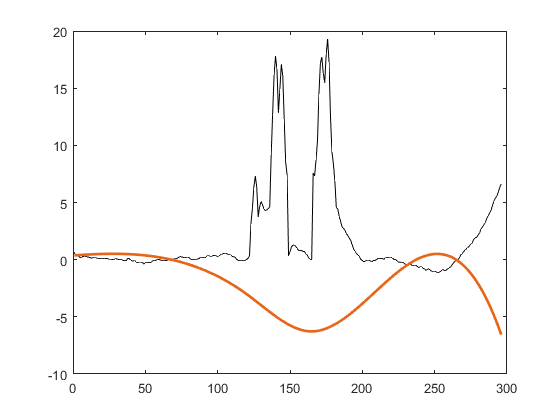

Cri_1=[];
AA=1;
XX=[30 35 40 45 50];
for BB=1:length(XX)
  [up9,low_test9] = envelope(Test9_st40,XX(BB),'peak');
  param_small = {'Color',[0.9 0.4 0.1],'Linewidth',2};
  
  Test9_st40_TRY=Test9_st40-low_test9;
  Cri_1(AA)=[abs(Test9_st40_TRY(131,1))];
  AA=AA+1;
end
Index = find(Cri_1==min(Cri_1));

if length(Index)>1
    Index=Index(1)
end


[up9,low_test9] = envelope(Test9_st40,XX(Index),'peak');
Test9_st40=Test9_st40-low_test9;
% min(Cri_1)


figure
plot(Test9_st40,'k', 'Linewidth', 1)
hold on
plot(low_test9,param_small{:});
hold off

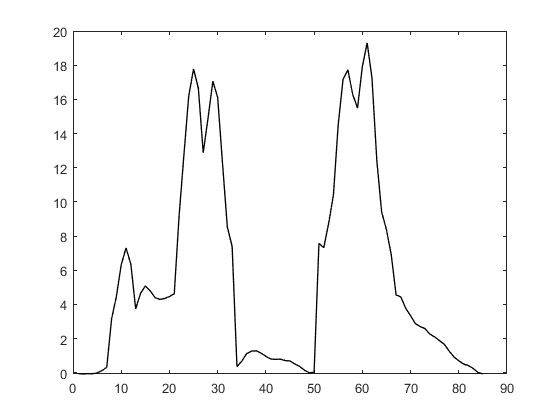

Test9_st40=Test9_st40(116:200);
figure
plot(Test9_st40,'k', 'Linewidth', 1)

## Inputs

N_T9=5;          %% the number of axles
v1_T9=25;     %% m/s
f_T9=100;        %% Hz
d1_T9=0;         %% m
d2_T9=3.3528;      %% m
d3_T9=1.2192;      %% m
d4_T9=6.7056;     %% m
d5_T9=1.2192;      %% m


Weights_T9=[4.54 7.03 7.03 7.03 7.03];

D1_vec_T9=[d1_T9 d1_T9+d2_T9 d1_T9+d2_T9+d3_T9 d1_T9+d2_T9+d3_T9+d4_T9 d1_T9+d2_T9+d3_T9+d4_T9+d5_T9];

c1_T9=D1_vec_T9(1)*f_T9/v1_T9;
c2_T9=D1_vec_T9(2)*f_T9/v1_T9;
c3_T9=D1_vec_T9(3)*f_T9/v1_T9;
c4_T9=D1_vec_T9(4)*f_T9/v1_T9;
c5_T9=D1_vec_T9(5)*f_T9/v1_T9;

C1_vec_T9=round([c1_T9 c2_T9 c3_T9 c4_T9 c5_T9]);

[row1_T9 col1_T9]=size(Test9_st40);
k1_T9=row1_T9;                      %% Total number of scans

%%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
%%% Weight vector (created from a truck axle weights which is considered for calibration), and dataaa (strain data)

[A_mat_T9]=A_MATRIX(N_T9,k1_T9,C1_vec_T9,Weights_T9);


The tests 1-9 were all for RefIL calculation. These ILs are later computed and named IL17,18,19 for 3-axle, 4-axle, and 5-axle trucks. The following tests are to compute the thresholds. So, for each a new IL should be obtained (called IL 14,15,16) and then the SSE of the new IL and the RefILs should computed.

## Test 14 (3-axle_LANE2)

'6035_Intact_Multiple3axle_TP3 means that multiple trucks (two in-one-row 3axles) are moved on the second lane and on transverse position 3. This can be changed to other transverse positions by changing "TP3" to "TP2" or "TP1". Every time that we run the code a different noise content will be added to the strain response. So, to follow the procedure explained in my dissertation (chapter 4) for threshold computation, for each TP, the tests should be repeated three times to include three diffeernt noise content and the DI indicators should be manually written somewhere to be used later for threshold computation.  So, for each truck (3-axle, 4-axle, 5-axle) and event (single/multiple), nine DIs should be computed. Then, a 95% confidence analysis should be perfomed and the upper limit of the confidence interval is going to be the threshold for that particular truck and event. To perform the 95% analysis, an online website or Excel can be used.

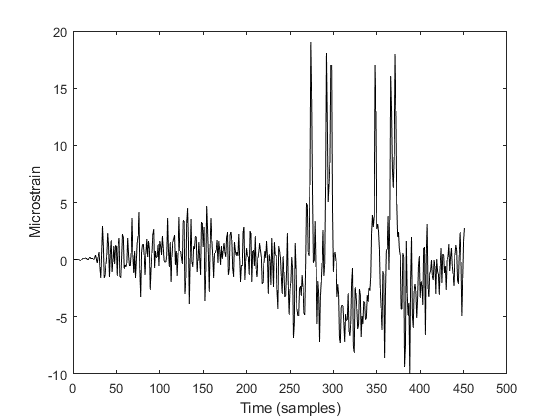

Data14 = textread('6035_Intact_Multiple3axle_TP3.txt');


plot(Data14,'k', 'Linewidth', 1)

xlabel('Time (samples)')
ylabel('Microstrain')

% 
Test14_st40=Data14;

Test14_st40=Test14_st40+0.4*randn(length(Test14_st40),1);

Test14_st40=Test14_st40';


% T1=Test2_st40(150:271);
% T2=Test2_st40(272:279);
% T3=Test2_st40(280:286);
% T4=Test2_st40(287:303);
% T5=Test2_st40(304:end-33);


T1=Test14_st40(150:271);
T2=Test14_st40(272:279);
T3=Test14_st40(280:286);
T4=Test14_st40(287:303);
T5=Test14_st40(304:342);

T6=Test14_st40(343:354);
T7=Test14_st40(355:364);
T8=Test14_st40(365:377);
T9=Test14_st40(378:end-33);


T1 = movmean(T1,[10 0]);
T2 = movmean(T2,[2 0]);
T3 = movmean(T3,[10 0]);
T4 = movmean(T4,[2 0]);
T5 = movmean(T5,[10 0]);
T6= movmean(T6,[2 0]);
T7 = movmean(T7,[10 0]);
T8 = movmean(T8,[2 0]);
T9 = movmean(T9,[10 0]);

Test14_st40=[T1 T2 T3 T4 T5 T6 T7 T8 T9];

Test14_st40=Test14_st40';


Cri_1=[];
AA=1;
XX=[30 35 40 45 50];
for BB=1:length(XX)
  [up14,low_test14] = envelope(Test14_st40,XX(BB),'peak');
  param_small = {'Color',[0.9 0.4 0.1],'Linewidth',2};
  
  Test14_st40_TRY=Test14_st40-low_test14;
  Cri_1(AA)=[abs(Test14_st40_TRY(131,1))];
  AA=AA+1;
end
Index = find(Cri_1==min(Cri_1));

if length(Index)>1
    Index=Index(1)
end


[up14,low_test14] = envelope(Test14_st40,XX(Index),'peak');
Test14_st40=Test14_st40-low_test14;
min(Cri_1)

ans = 2.9073

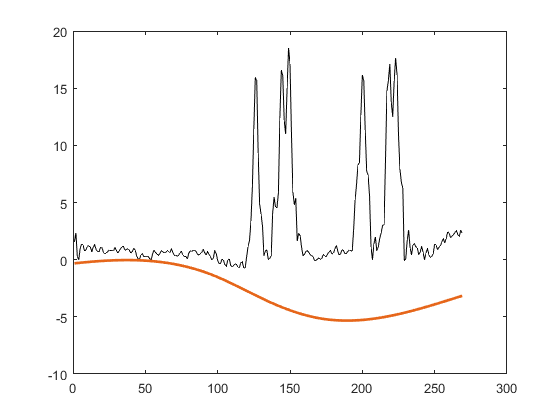

% The fitted curve may look weird but it still satisfies the requirements
% mentioned for the fitted curve in my dissertation (chapter 3)

figure
plot(Test14_st40,'k', 'Linewidth', 1)
hold on
plot(low_test14,param_small{:});
hold off

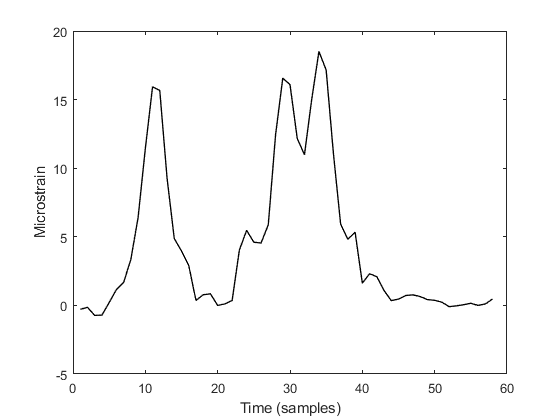

Test14_st40=Test14_st40(116:173);

plot(Test14_st40,'k', 'Linewidth', 1)

xlabel('Time (samples)')
ylabel('Microstrain')

## Inputs

N_T14=3;          %% the number of axles
v1_T14=25;     %% m/s
f_T14=100;        %% Hz
d1_T14=0;         %% m
d2_T14=4.5;      %% m
d3_T14=1.31;      %% m



Weights_T14=[9.1 7.1 7.1];

D1_vec_T14=[d1_T14 d1_T14+d2_T14 d1_T14+d2_T14+d3_T14];

c1_T14=D1_vec_T14(1)*f_T14/v1_T14;
c2_T14=D1_vec_T14(2)*f_T14/v1_T14;
c3_T14=D1_vec_T14(3)*f_T14/v1_T14;


C1_vec_T14=round([c1_T14 c2_T14 c3_T14]);

[row1_T14 col1_T14]=size(Test14_st40);
k1_T14=row1_T14;                      %% Total number of scans

%%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
%%% Weight vector (created from a truck axle weights which is considered for calibration), and dataaa (strain data)

[A_mat_T14]=A_MATRIX(N_T14,k1_T14,C1_vec_T14,Weights_T14);


## Test 15 (4-axle_LANE2)

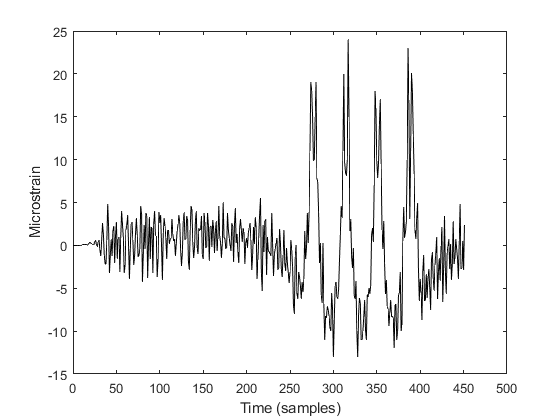

Data15 = textread('6035_Intact_Multiple4axle_TP3.txt');
plot(Data15,'k', 'Linewidth', 1)

xlabel('Time (samples)')
ylabel('Microstrain')

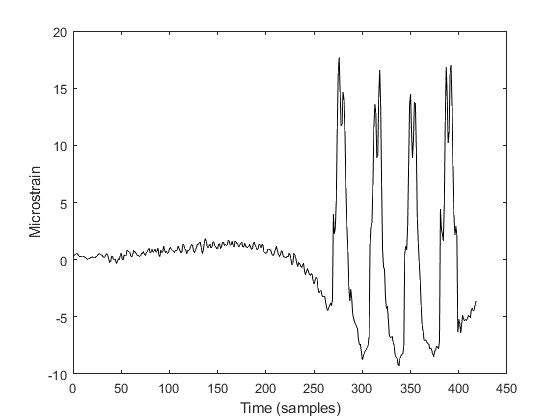

Test15_st40=Data15;

Test15_st40=Test15_st40+0.4*randn(length(Test15_st40),1);

Test15_st40=Test15_st40';

T1=Test15_st40(1:269);
T2=Test15_st40(270:284);
T3=Test15_st40(285:307);
T4=Test15_st40(308:322);
T5=Test15_st40(323:343);

T6=Test15_st40(344:360);
T7=Test15_st40(361:380);
T8=Test15_st40(381:398);
T9=Test15_st40(399:end-33);


T1 = movmean(T1,[10 0]);
T2 = movmean(T2,[2 0]);

T3 = movmean(T3,[10 0]);
T4 = movmean(T4,[2 0]);

T5 = movmean(T5,[10 0]);
T6 = movmean(T6,[2 0]);

T7 = movmean(T7,[10 0]);
T8 = movmean(T8,[2 0]);
T9 = movmean(T9,[10 0]);




Test15_st40=[T1 T2 T3 T4 T5 T6 T7 T8 T9];
Test15_st40=Test15_st40';

figure
plot(Test15_st40,'k', 'Linewidth', 1)

xlabel('Time (samples)')
ylabel('Microstrain')

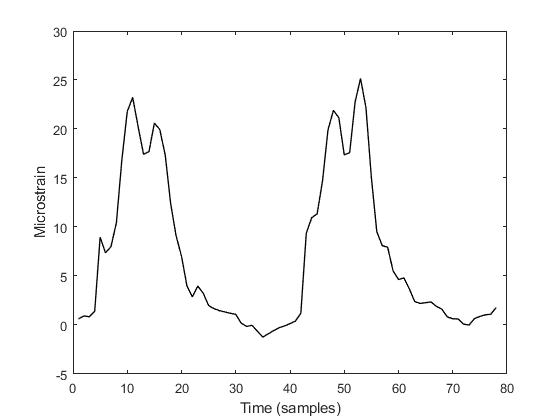


Cri_1=[];
AA=1;
XX=[30 35 40 45 50];
for BB=1:length(XX)
  [up15,low_test15] = envelope(Test15_st40,XX(BB),'peak');
  param_small = {'Color',[0.9 0.4 0.1],'Linewidth',2};
  
  Test15_st40_TRY=Test15_st40-low_test15;
  Cri_1(AA)=[abs(Test15_st40_TRY(131,1))];
  AA=AA+1;
end
Index = find(Cri_1==min(Cri_1));

if length(Index)>1
    Index=Index(1)
end


[up15,low_test15] = envelope(Test15_st40,XX(Index),'peak');
Test15_st40=Test15_st40-low_test15;
% min(Cri_1)


% figure
% plot(Test15_st40,'k', 'Linewidth', 1)
% hold on
% plot(low_test15,param_small{:});
% 
% xlabel('Time (samples)')
% ylabel('Microstrain')
% 
% legend('Original response','Localized strain')
% 
% hold off
Test15_st40=Test15_st40(266:343);
figure
plot(Test15_st40,'k', 'Linewidth', 1)
xlabel('Time (samples)')
ylabel('Microstrain')

## Inputs

N_T15=4;          %% the number of axles
v1_T15=25;     %% m/s
f_T15=100;        %% Hz
d1_T15=0;         %% m
d2_T15=1.4;      %% m
d3_T15=8;      %% m
d4_T15=1.4;     %% m



Weights_T15=[9 9 9 9];

D1_vec_T15=[d1_T15 d1_T15+d2_T15 d1_T15+d2_T15+d3_T15 d1_T15+d2_T15+d3_T15+d4_T15];

c1_T15=D1_vec_T15(1)*f_T15/v1_T15;
c2_T15=D1_vec_T15(2)*f_T15/v1_T15;
c3_T15=D1_vec_T15(3)*f_T15/v1_T15;
c4_T15=D1_vec_T15(4)*f_T15/v1_T15;


C1_vec_T15=round([c1_T15 c2_T15 c3_T15 c4_T15]);

[row1_T15 col1_T15]=size(Test15_st40);
k1_T15=row1_T15;                      %% Total number of scans

%%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
%%% Weight vector (created from a truck axle weights which is considered for calibration), and dataaa (strain data)

[A_mat_T15]=A_MATRIX(N_T15,k1_T15,C1_vec_T15,Weights_T15);


## Test 16 (5-axle_LANE2)

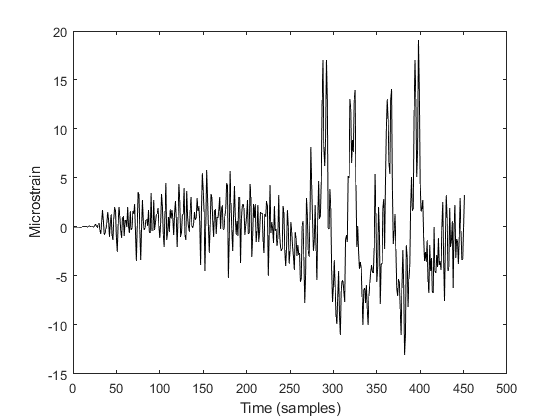

Data16 = textread('6035_Intact_Multiple5axle_TP3.txt');
plot(Data16,'k', 'Linewidth', 1)

xlabel('Time (samples)')
ylabel('Microstrain')

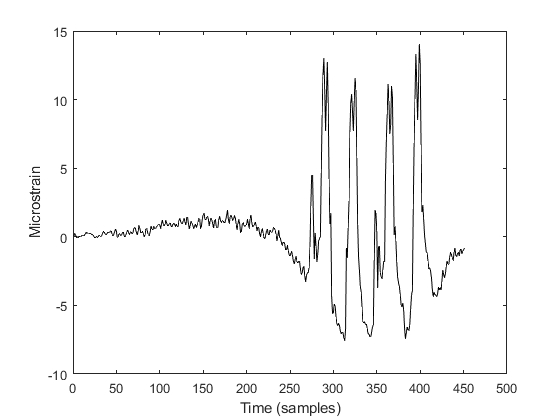

% 
Test16_st40=Data16;


Test16_st40=Test16_st40+0.4*randn(length(Test16_st40),1);


Test16_st40=Test16_st40';

T1=Test16_st40(1:271);
T2=Test16_st40(272:277);
T3=Test16_st40(278:285);
T4=Test16_st40(286:297);
T5=Test16_st40(298:314);
T6=Test16_st40(315:330);
T7=Test16_st40(331:346);

T8=Test16_st40(347:350);
T9=Test16_st40(351:359);
T10=Test16_st40(360:369);
T11=Test16_st40(370:391);
T12=Test16_st40(392:401);
T13=Test16_st40(402:end);

T1 = movmean(T1,[10 0]);
T2 = movmean(T2,[2 0]);
T3 = movmean(T3,[10 0]);
T4 = movmean(T4,[2 0]);
T5 = movmean(T5,[10 0]);
T6 = movmean(T6,[2 0]);
T7 = movmean(T7,[10 0]);
T8 = movmean(T8,[2 0]);
T9 = movmean(T9,[10 0]);
T10 = movmean(T10,[2 0]);
T11 = movmean(T11,[10 0]);
T12 = movmean(T12,[2 0]);
T13 = movmean(T13,[10 0]);

Test16_st40=[T1 T2 T3 T4 T5 T6 T7 T8 T9 T10 T11 T12 T13];
Test16_st40=Test16_st40';

figure
plot(Test16_st40,'k', 'Linewidth', 1)

xlabel('Time (samples)')
ylabel('Microstrain')

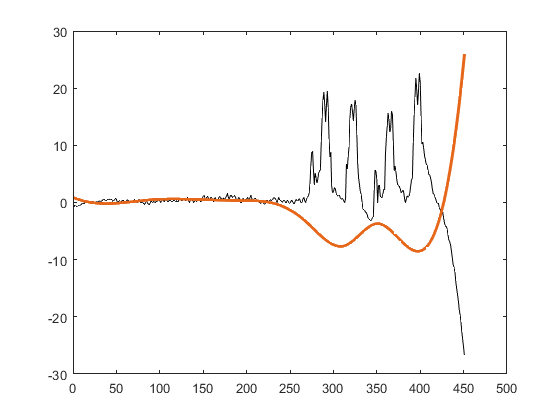


Cri_1=[];
AA=1;
XX=[30 35 40 45 50];
for BB=1:length(XX)
  [up16,low_test16] = envelope(Test16_st40,XX(BB),'peak');
  param_small = {'Color',[0.9 0.4 0.1],'Linewidth',2};
  
  Test16_st40_TRY=Test16_st40-low_test16;
  Cri_1(AA)=[abs(Test16_st40_TRY(131,1))];
  AA=AA+1;
end
Index = find(Cri_1==min(Cri_1));

if length(Index)>1
    Index=Index(1)
end


[up16,low_test16] = envelope(Test16_st40,XX(Index),'peak');
Test16_st40=Test16_st40-low_test16;
% min(Cri_1)


% figure
% plot(Test16_st40,'k', 'Linewidth', 1)
% hold on
% plot(low_test16,param_small{:});
% hold off

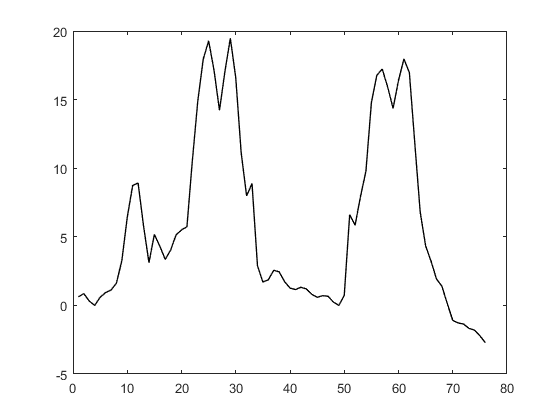

Test16_st40=Test16_st40(265:340);
figure
plot(Test16_st40,'k', 'Linewidth', 1)

## Inputs

N_T16=5;          %% the number of axles
v1_T16=25;     %% m/s
f_T16=100;        %% Hz
d1_T16=0;         %% m
d2_T16=3.3528;      %% m
d3_T16=1.2192;      %% m
d4_T16=6.7056;     %% m
d5_T16=1.2192;      %% m


Weights_T16=[4.54 7.03 7.03 7.03 7.03];

D1_vec_T16=[d1_T16 d1_T16+d2_T16 d1_T16+d2_T16+d3_T16 d1_T16+d2_T16+d3_T16+d4_T16 d1_T16+d2_T16+d3_T16+d4_T16+d5_T16];

c1_T16=D1_vec_T16(1)*f_T16/v1_T16;
c2_T16=D1_vec_T16(2)*f_T16/v1_T16;
c3_T16=D1_vec_T16(3)*f_T16/v1_T16;
c4_T16=D1_vec_T16(4)*f_T16/v1_T16;
c5_T16=D1_vec_T16(5)*f_T16/v1_T16;

C1_vec_T16=round([c1_T16 c2_T16 c3_T16 c4_T16 c5_T16]);

[row1_T16 col1_T16]=size(Test16_st40);
k1_T16=row1_T16;                      %% Total number of scans

%%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
%%% Weight vector (created from a truck axle weights which is considered for calibration), and dataaa (strain data)

[A_mat_T16]=A_MATRIX(N_T16,k1_T16,C1_vec_T16,Weights_T16);

hold off

## Influence Line 

## RefIL for the 3-axle truck

%% 3axle
Inf_Line17=inv(A_mat_T1'*A_mat_T1+A_mat_T2'*A_mat_T2+A_mat_T3'*A_mat_T3)*(A_mat_T1'*Test1_st40+A_mat_T2'*Test2_st40+A_mat_T3'*Test3_st40);


## RefIL for the 4-axle truck

%% 4axle
Inf_Line18=inv(A_mat_T4'*A_mat_T4+A_mat_T5'*A_mat_T5+A_mat_T6'*A_mat_T6)*(A_mat_T4'*Test4_st40+A_mat_T5'*Test5_st40+A_mat_T6'*Test6_st40);


## RefIL for the 5-axle truck

%% 5axle
Inf_Line19=inv(A_mat_T7'*A_mat_T7+A_mat_T8'*A_mat_T8+A_mat_T9'*A_mat_T9)*(A_mat_T7'*Test7_st40+A_mat_T8'*Test8_st40+A_mat_T9'*Test9_st40);


Inf_Line21=inv(A_mat_T14'*A_mat_T14)*(A_mat_T14'*Test14_st40);
Inf_Line22=inv(A_mat_T15'*A_mat_T15)*(A_mat_T15'*Test15_st40);
Inf_Line23=inv(A_mat_T16'*A_mat_T16)*(A_mat_T16'*Test16_st40);



## Influence Line 

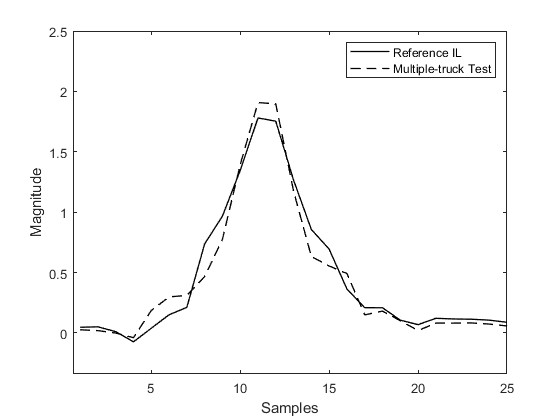

%%% Not that necessary, but here, I am just smoothing the unnecessary parts of the ILs.


Inf_Line17=Inf_Line17';
Inf_Line17=[(movmean(Inf_Line17(1:3),[20 0])) Inf_Line17(4:20) movmean(Inf_Line17(21:end),[0 20])];


Inf_Line18=Inf_Line18';
Inf_Line18=[(movmean(Inf_Line18(1:3),[20 0])) Inf_Line18(4:20) movmean(Inf_Line18(21:end),[0 20])];


Inf_Line19=Inf_Line19';
Inf_Line19=[(movmean(Inf_Line19(1:3),[20 0])) Inf_Line19(4:20) movmean(Inf_Line19(21:end),[0 20])];



Inf_Line21=Inf_Line21';
Inf_Line21=[(movmean(Inf_Line21(1:3),[20 0])) Inf_Line21(4:20) movmean(Inf_Line21(21:end),[0 20])];


Inf_Line22=Inf_Line22';
Inf_Line22=[(movmean(Inf_Line22(1:3),[20 0])) Inf_Line22(4:20) movmean(Inf_Line22(21:end),[0 20])];

% Inf_Line23=Inf_Line23';
% Inf_Line23=[(movmean(Inf_Line23(1:3),[20 0])) Inf_Line23(4:20) movmean(Inf_Line23(21:end),[0 20])];
% % 



%%% Plot the REF IL for single-truck event vs. the IL of the multiple case

figure
plot(Inf_Line17, '-k','Linewidth', 1)
hold on
plot(Inf_Line21, '--k', 'Linewidth', 1)
xlabel('Samples')
ylabel('Magnitude')
legend('Reference IL','Multiple-truck Test')

xlim([0.6 25])
ylim([-0.34 2.5])

%%% SSE of IL for single-truck (3-axle) event vs. the IL of the multiple case

BB=0;
for i=1:length(Inf_Line17)
PPP=[Inf_Line17(i)-Inf_Line21(i)]^2;
BB=BB+PPP;
end

DLocator=BB

DLocator = 0.3203

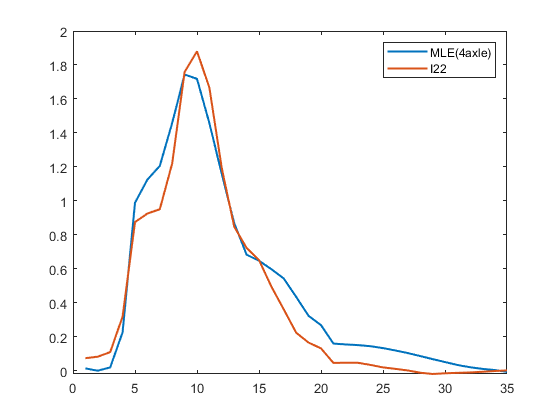


%%% SSE of IL for single-truck (4-axle) event vs. the IL of the multiple case

figure
plot(Inf_Line18, 'Linewidth', 1.5)
hold on
plot(Inf_Line22, 'Linewidth', 1.5)
legend('MLE(4axle)','I22')

BB=0;
for i=1:length(Inf_Line18)
PPP=[Inf_Line18(i)-Inf_Line22(i)]^2;
BB=BB+PPP;
end

DLocator=BB

DLocator = 0.5140

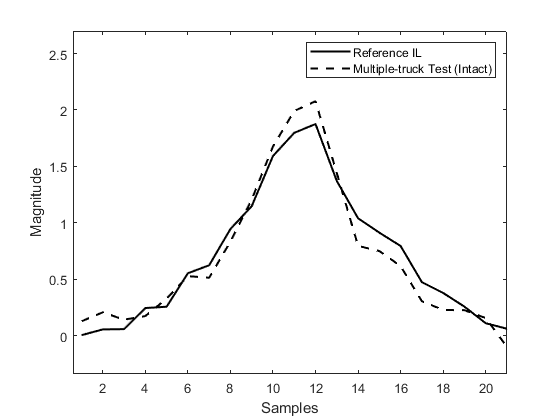


%%% SSE of IL for single-truck (5-axle) event vs. the IL of the multiple case

Inf_Line19=Inf_Line19(1:end-9);
figure
plot(Inf_Line19,'-k','Linewidth', 1.5)
hold on
plot(Inf_Line23, '--k','Linewidth', 1.5)
xlabel('Samples')
ylabel('Magnitude')
legend('Reference IL','Multiple-truck Test (Intact)')

xlim([0.6 21])
ylim([-0.34 2.7])

BB=0;
for i=1:length(Inf_Line19)
PPP=[Inf_Line19(i)-Inf_Line23(i)]^2;
BB=BB+PPP;
end

DLocator=BB

DLocator = 0.4205